% close all; clear;
d = 10;
k = 3;
n = 500;
[X,label] = mixGaussRnd(d,k,n);
%plotClass(X,label);
m = floor(n/2);
X1 = X(:,1:m);
X2 = X(:,(m+1):end);
% train
[z1,model,llh] = mixGaussEm(X1,k);

EM for Gaussian mixture: running ... 


figure;
%plot(llh);
figure;
%plotClass(X1,z1);
num_correct = sum(label(1:m)==z1)

num_correct = 195

acc_train = num_correct/250.0*100

acc_train = 78

% predict
z2 = mixGaussPred(X2,model);
figure;
%plotClass(X2,z2);
num_correct = sum(label((m+1):end)==z2)

num_correct = 225

acc_test = num_correct/250.0*100

acc_test = 90

a = [1 0 2 0 1 0];
b = [1 1 2 1 1 0];
c= sum(a==b)

c = 4

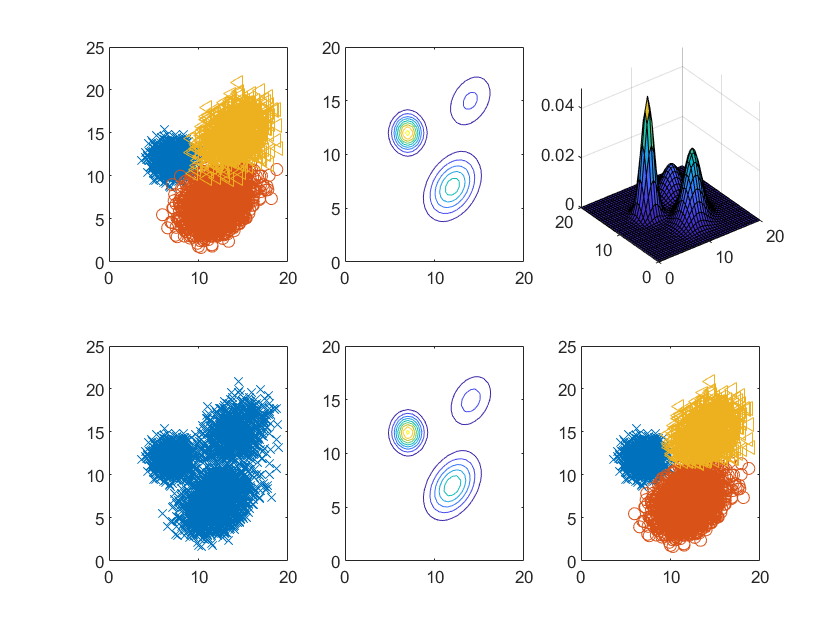

close all;
clear;
clc;

%% Sample Generate
N=5000;
a_real =[3/10,5/10,2/10];
mu_real = [7,12;12,7;14,15];
cov_real(:,:,1) = [1,0;0,1];
cov_real(:,:,2) = [3,1;1,3];
cov_real(:,:,3) = [3,1;1,3];
X_1 = mvnrnd(mu_real(1,:),cov_real(:,:,1),N*a_real(1));
X_2 = mvnrnd(mu_real(2,:),cov_real(:,:,2),N*a_real(2));
X_3 = mvnrnd(mu_real(3,:),cov_real(:,:,2),N*a_real(3));

X=[X_1;X_2;X_3];
X = X(randperm(size(X,1)),:);

%% Sample Ploting
x = 0:0.5:20;
y = 0:0.5:20;
[x y]=meshgrid(x,y);
mesh = [x(:),y(:)];

z_real = a_real(1)*mvnpdf(mesh,mu_real(1,:),cov_real(:,:,1))+...
        a_real(2)* mvnpdf(mesh,mu_real(2,:),cov_real(:,:,2))+...
        a_real(3)* mvnpdf(mesh,mu_real(3,:),cov_real(:,:,3));
subplot(2,3,1);
plot(X_1(:,1),X_1(:,2),'x',X_2(:,1),X_2(:,2),'o',X_3(:,1),X_3(:,2),'<')

subplot(2,3,2);
contour(x,y,reshape(z_real,size(x,2),size(y,2)));

subplot(2,3,3);
surf(x,y,reshape(z_real,size(x,2),size(y,2)));

subplot(2,3,4);
plot(X(:,1),X(:,2),'x');
%%subplot(2,2,3);
%%surf(x,y,reshape(z_real,size(x,2),size(y,2)));
%%shading interp;

%% Parameter Initialization
a = [1/3, 1/3,1/3];
cov(:,:,1) = [1,0;0,1];
cov(:,:,2) = [1,0;0,1];
cov(:,:,3) = [1,0;0,1];
mu_y_init = (max(X(:,1))+min(X(:,1)))/2;
mu_x1_init = max(X(:,2))/4+3*min(X(:,2))/4;
mu_x2_init = 2*max(X(:,2))/4+2*min(X(:,2))/4;
mu_x3_init = 3*max(X(:,2))/4+1*min(X(:,2))/4;
w = zeros(size(X,1),length(a)); %%w(i,j),i是样本数量，j是聚类数量，w(i,j)的值表示样本i属于聚类j的概率，最大值表示i的聚类
mu = [mu_x1_init,mu_y_init;mu_x2_init,mu_y_init;mu_x3_init,mu_y_init];

%% EM Implementation
iter = 40;
for i = 1:iter
    %% Expectaion: 根据现有的（最新得到的）高斯分布和先验概率，计算每一个样本属于每一个聚类的概率
    for j = 1 : length(a)
        w(:,j)=a(j)*mvnpdf(X,mu(j,:),cov(:,:,j));
    end   
w=w./repmat(sum(w,2),1,size(w,2)); %%为了方便./计算，建立一个和w一样规模的矩阵，矩阵的列是相同的，每一行是w(:,1)+w(:,2)的值

%% Maximum: 根据现有的（最新得到的）的每一个样本属于每一个聚类的概率，计算先验概率和高斯参数
    a = sum(w,1)./size(w,1); %%把w的每一行加起来就能得到每一个聚类的先验概率
    
    mu = w'*X; %%分别得到X每一维对于每一个聚类的期望，mu(i,j),i是维数，j是聚类数
    mu= mu./repmat((sum(w,1))',1,size(mu,2));
        
    for j = 1 : length(a)
        vari = repmat(w(:,j),1,size(X,2)).*(X- repmat(mu(j,:),size(X,1),1)); %%得到一个特定聚类X每一维的方差矩阵，乘以w，（相当于选择出属于该聚类的X）
        cov(:,:,j) = (vari'*vari)/sum(w(:,j),1);      
    end
end

%% Estimation
[c estimate] = max(w,[],2);

%% Estimation Plotting
z = a(1)*mvnpdf(mesh,mu(1,:),cov(:,:,1))+...
        a(2)* mvnpdf(mesh,mu(2,:),cov(:,:,2))+...
        a(3)* mvnpdf(mesh,mu(3,:),cov(:,:,3));
subplot(2,3,5);
contour(x,y,reshape(z,size(x,2),size(y,2)));

one = find(estimate==1); 
two = find(estimate == 2);
three = find(estimate == 3);
% Plot Examples
subplot(2,3,6);
plot(X(one, 1), X(one, 2), 'x',X(two, 1), X(two, 2), 'o', X(three, 1), X(three, 2), '<');

%plot(X(neg, 1), X(neg, 2), 'o');

%% Build-in EM Implementation

%options = statset('Display','final');
%gm = gmdistribution.fit(X,2,'Options',options);
%subplot(2,2,4);
%ezcontour(@(x,y)pdf(gm,[x y]),[0 20],[0 20]);